# Opcion A

# Exercici 1

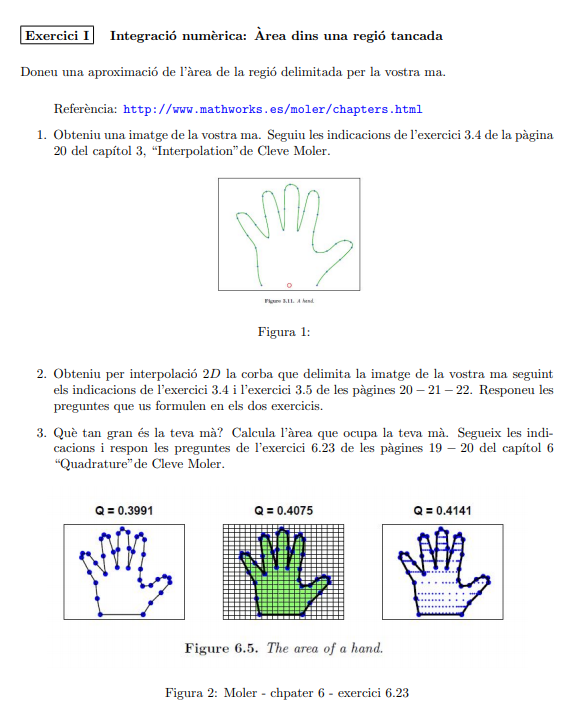

**Exercici 1.2**

clear
format long G
figure('position',get(0,'screensize'))
axes('position',[0 0 1 1])
%[x,y] = ginput;
load myhand.mat

# Splinetx

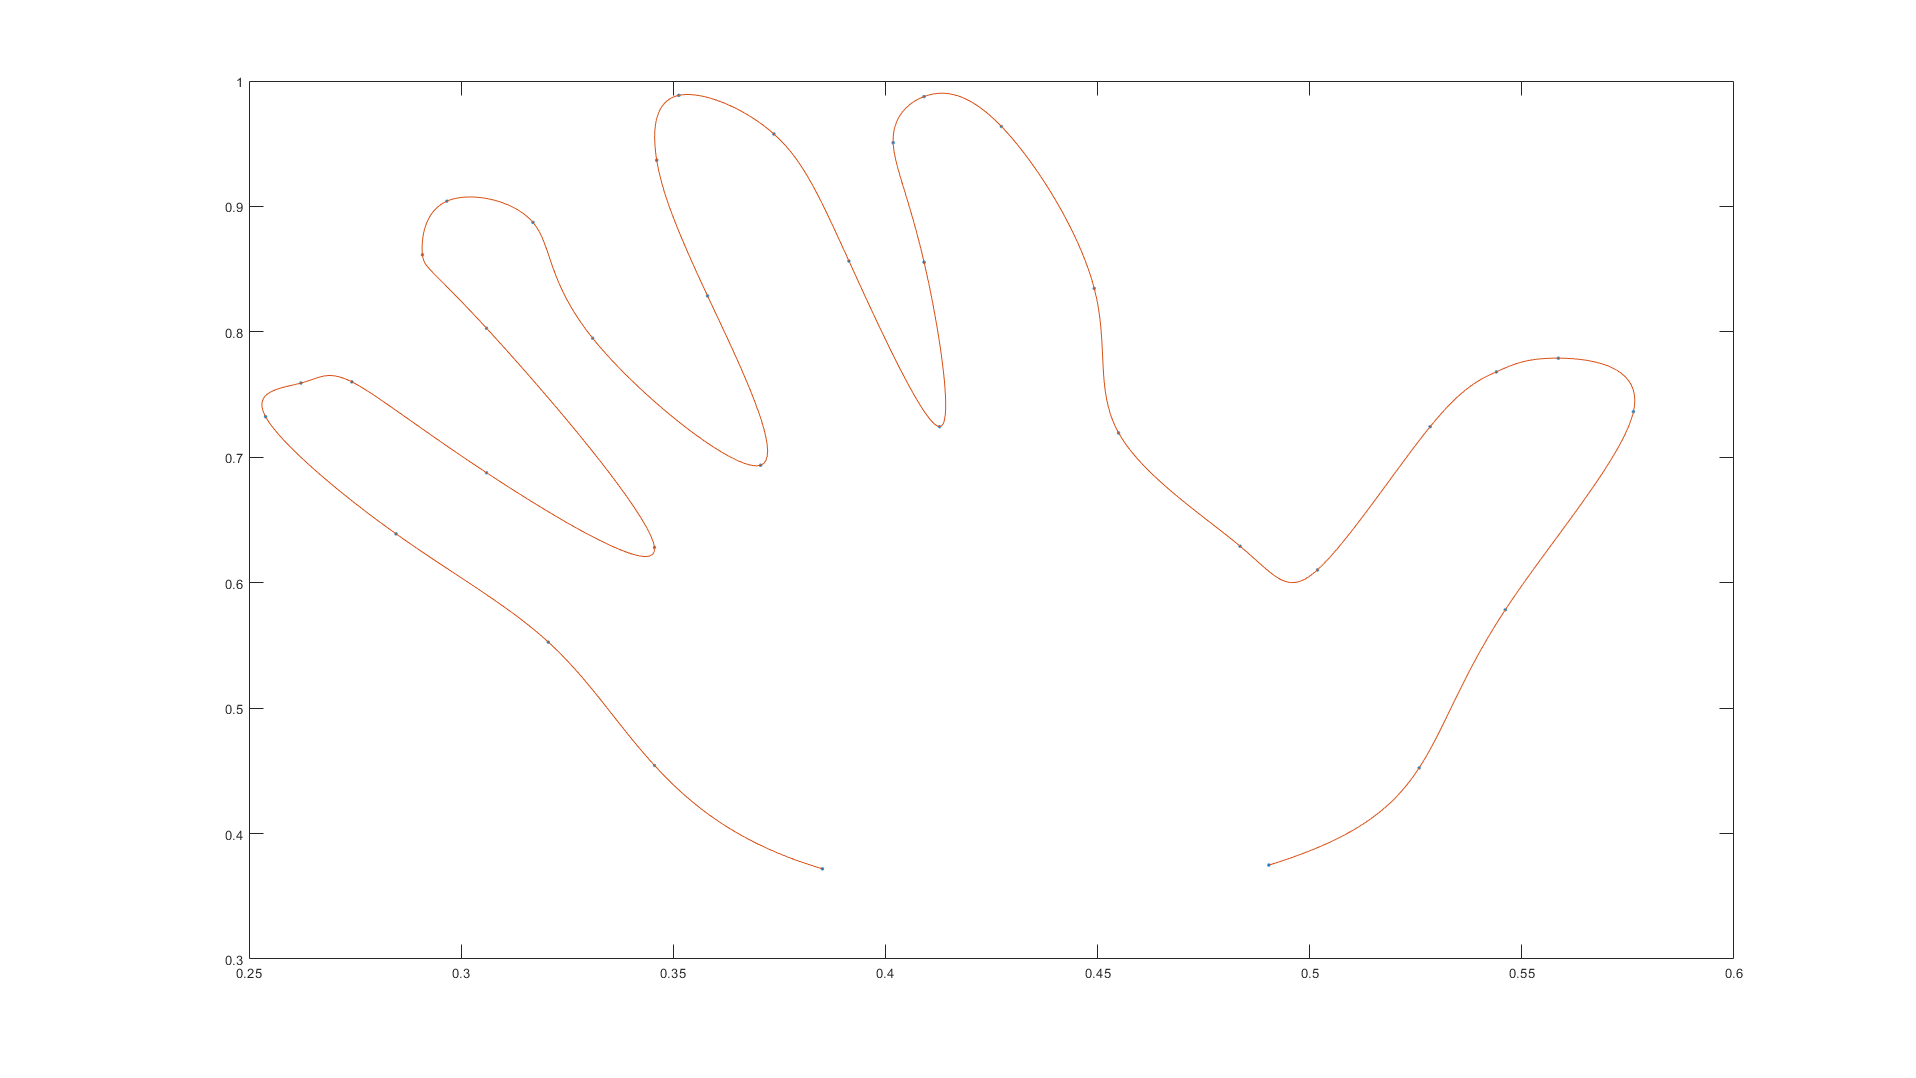

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,x,t);
v = splinetx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

# pchiptx

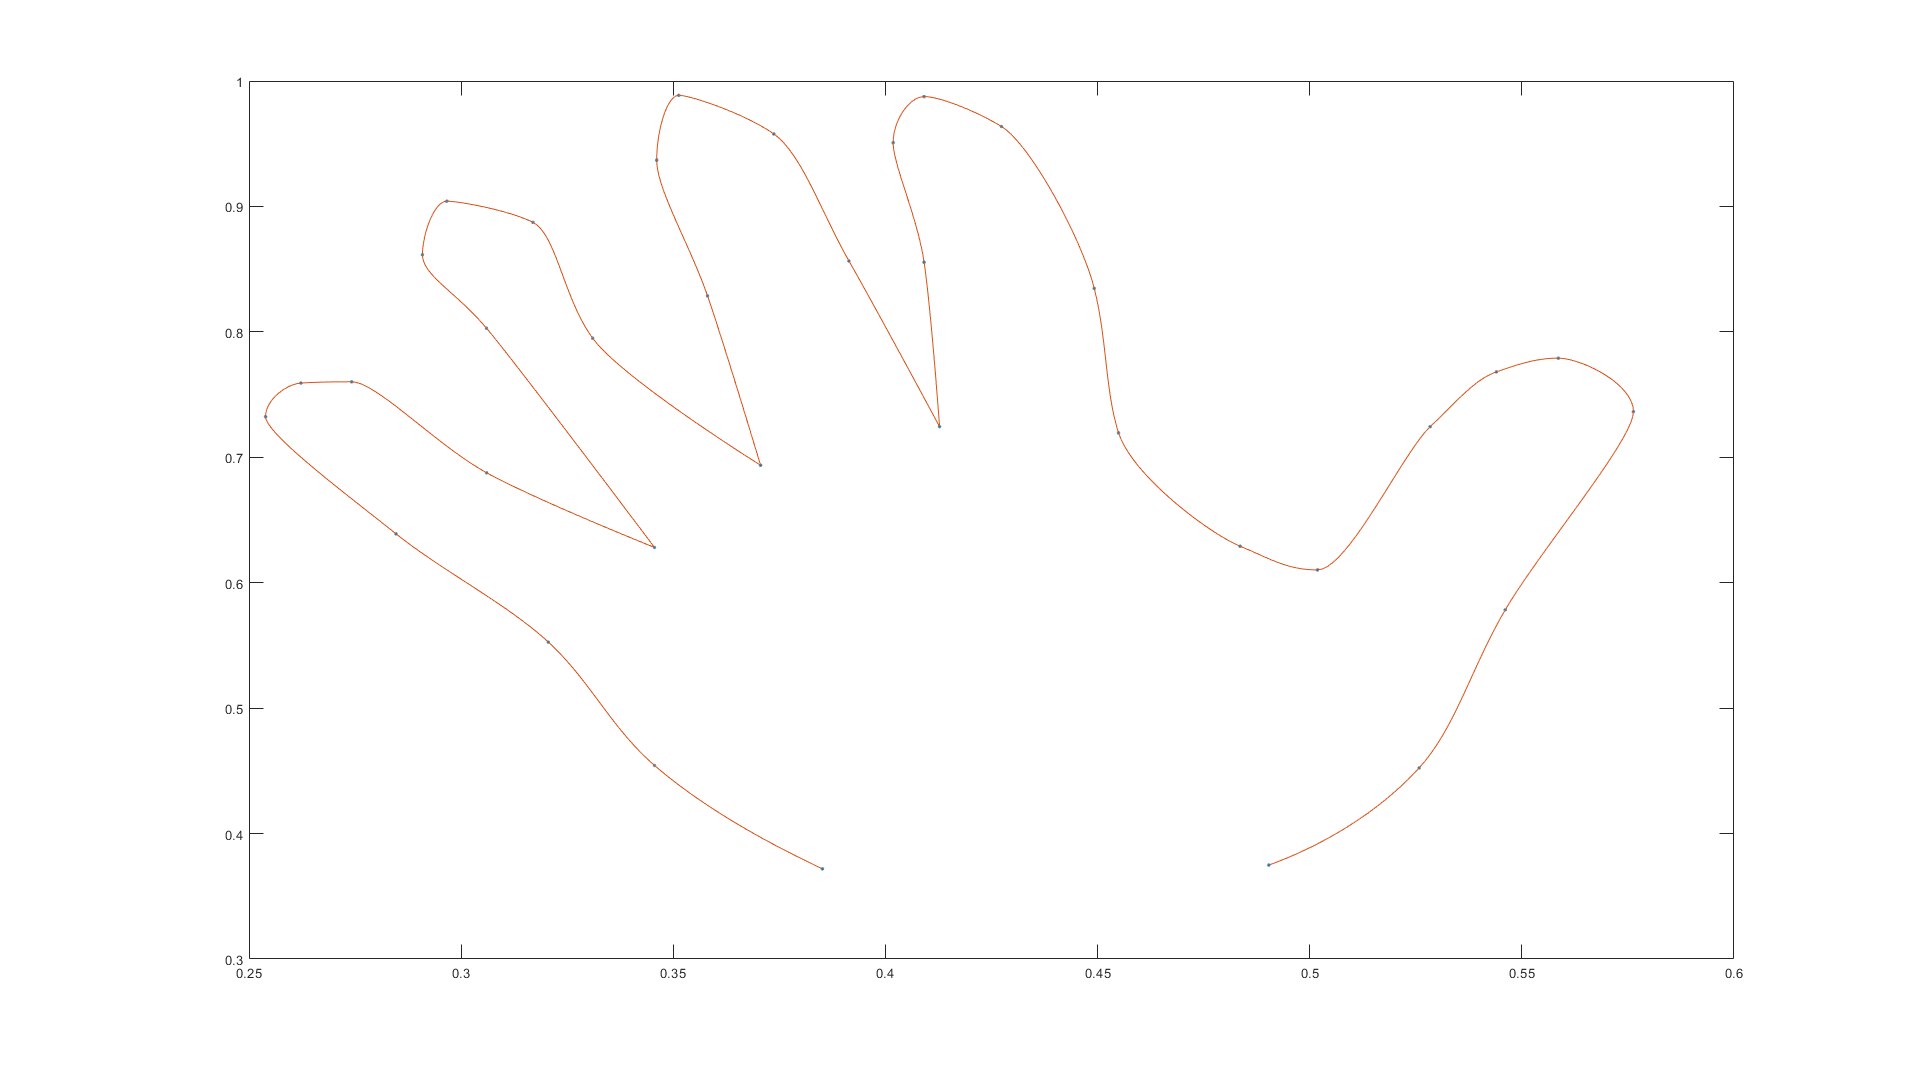

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = pchiptx(s,x,t);
v = pchiptx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

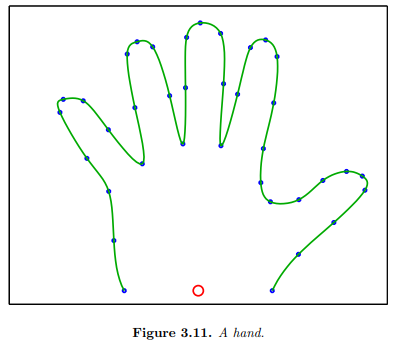

Mas o menos los plots de las manos son parecidas. Aun así prefiero la interpolacion con splinetx ya que hace mejor la forma curvada de la punta de los dedos. Creo que la figura 3.11 se ha hecho con splinetx.

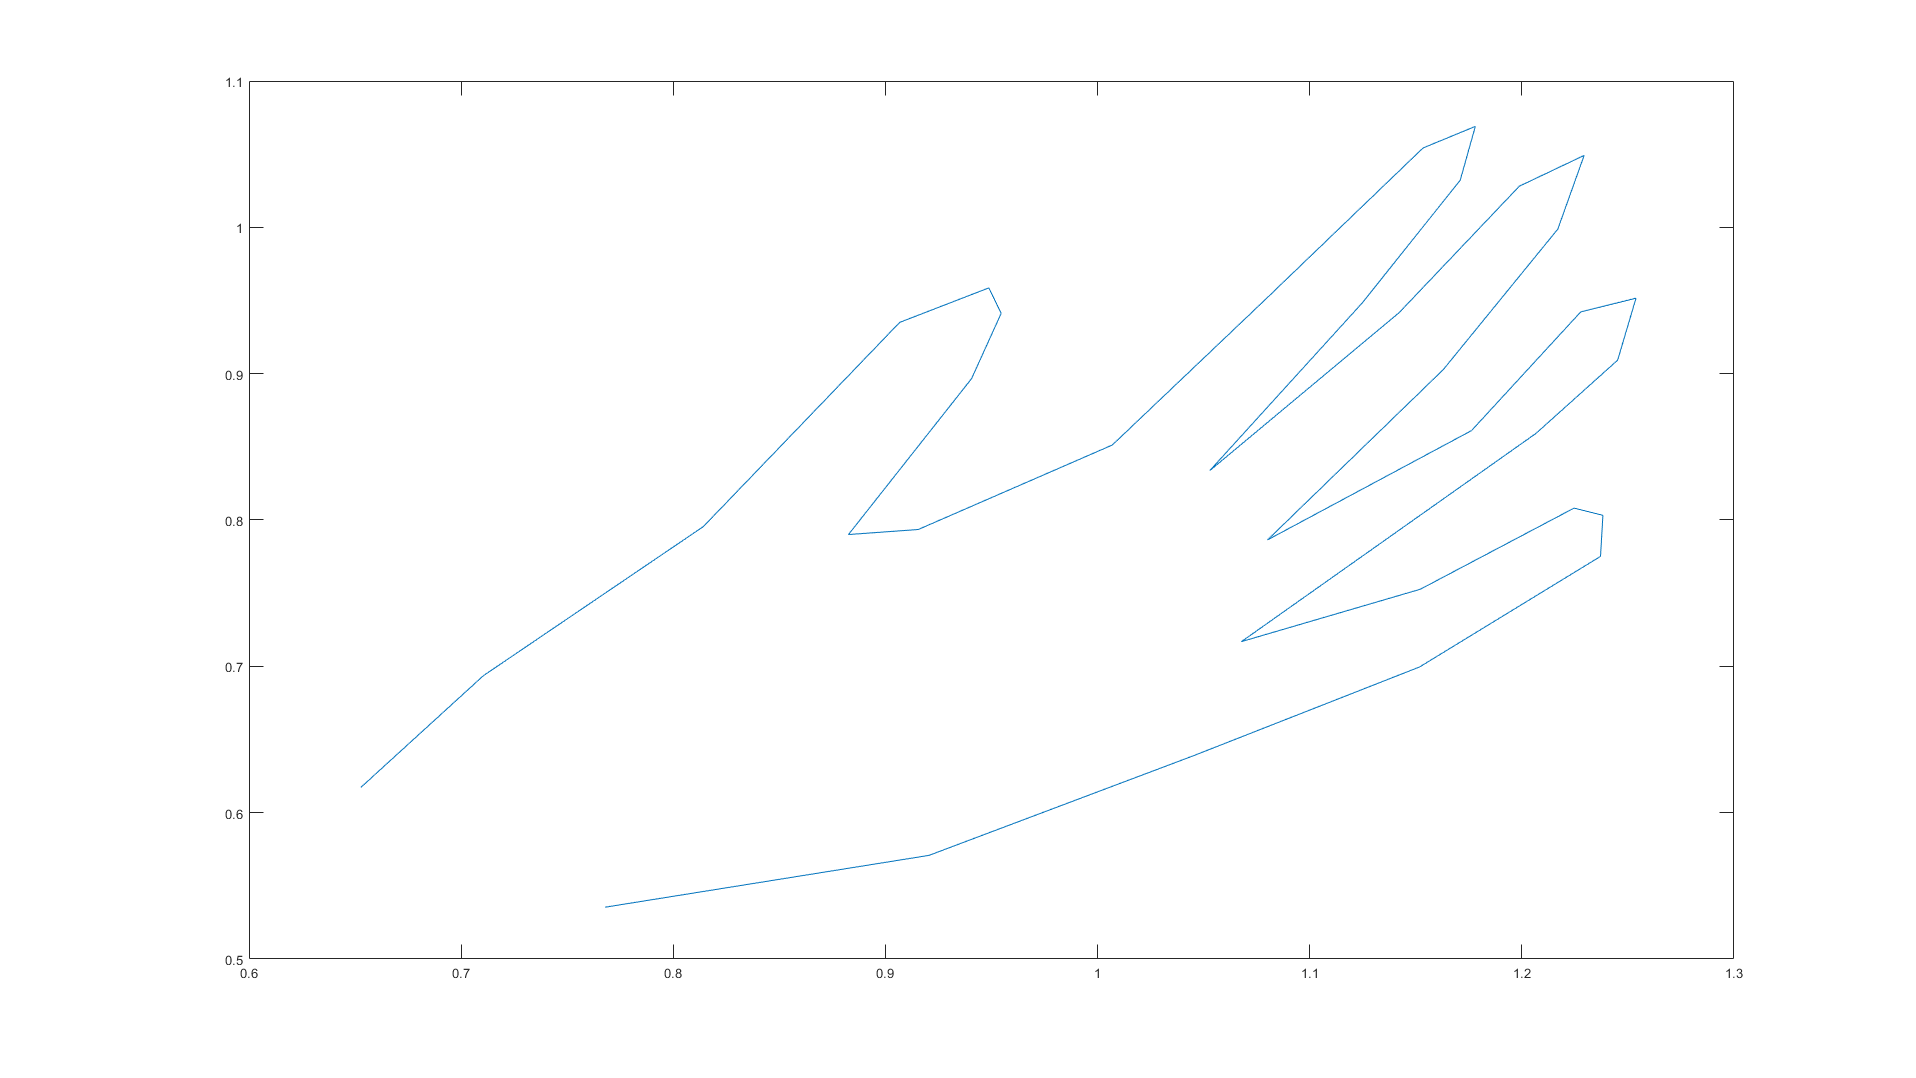

x0 = 0;
y0 =0;
x = x -x0;
y = y - y0;
theta = atan2(y,x);
r = sqrt(x.^2 + y.^2);
plot(theta,r);

delta = .05;
t = (theta(1):delta:theta(end))';
p = pchiptx(theta,r,t);
s = splinetx(theta,r,t)


s =

  0×1 empty double column vector



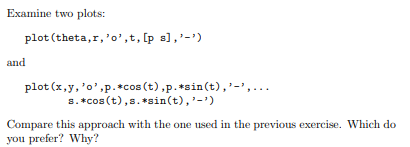

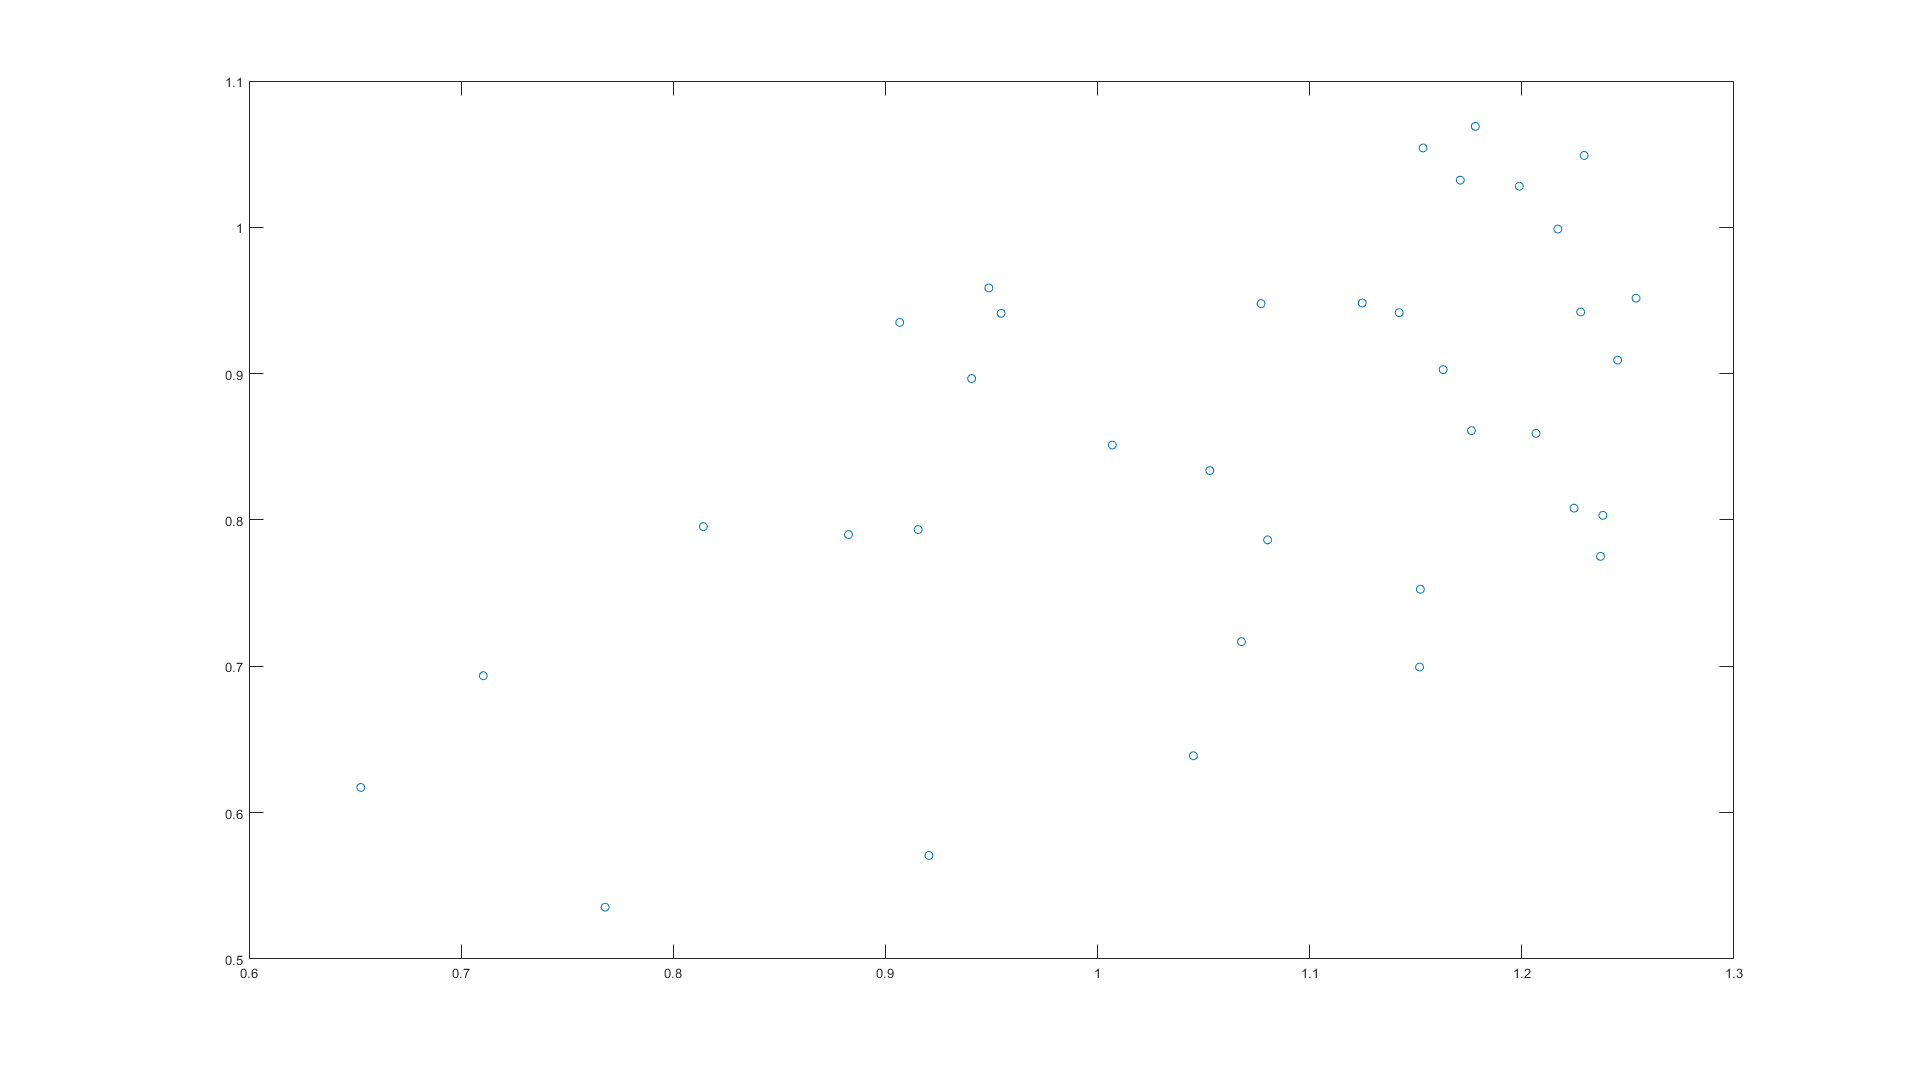

plot(theta,r,'o',t,[p s],'-')

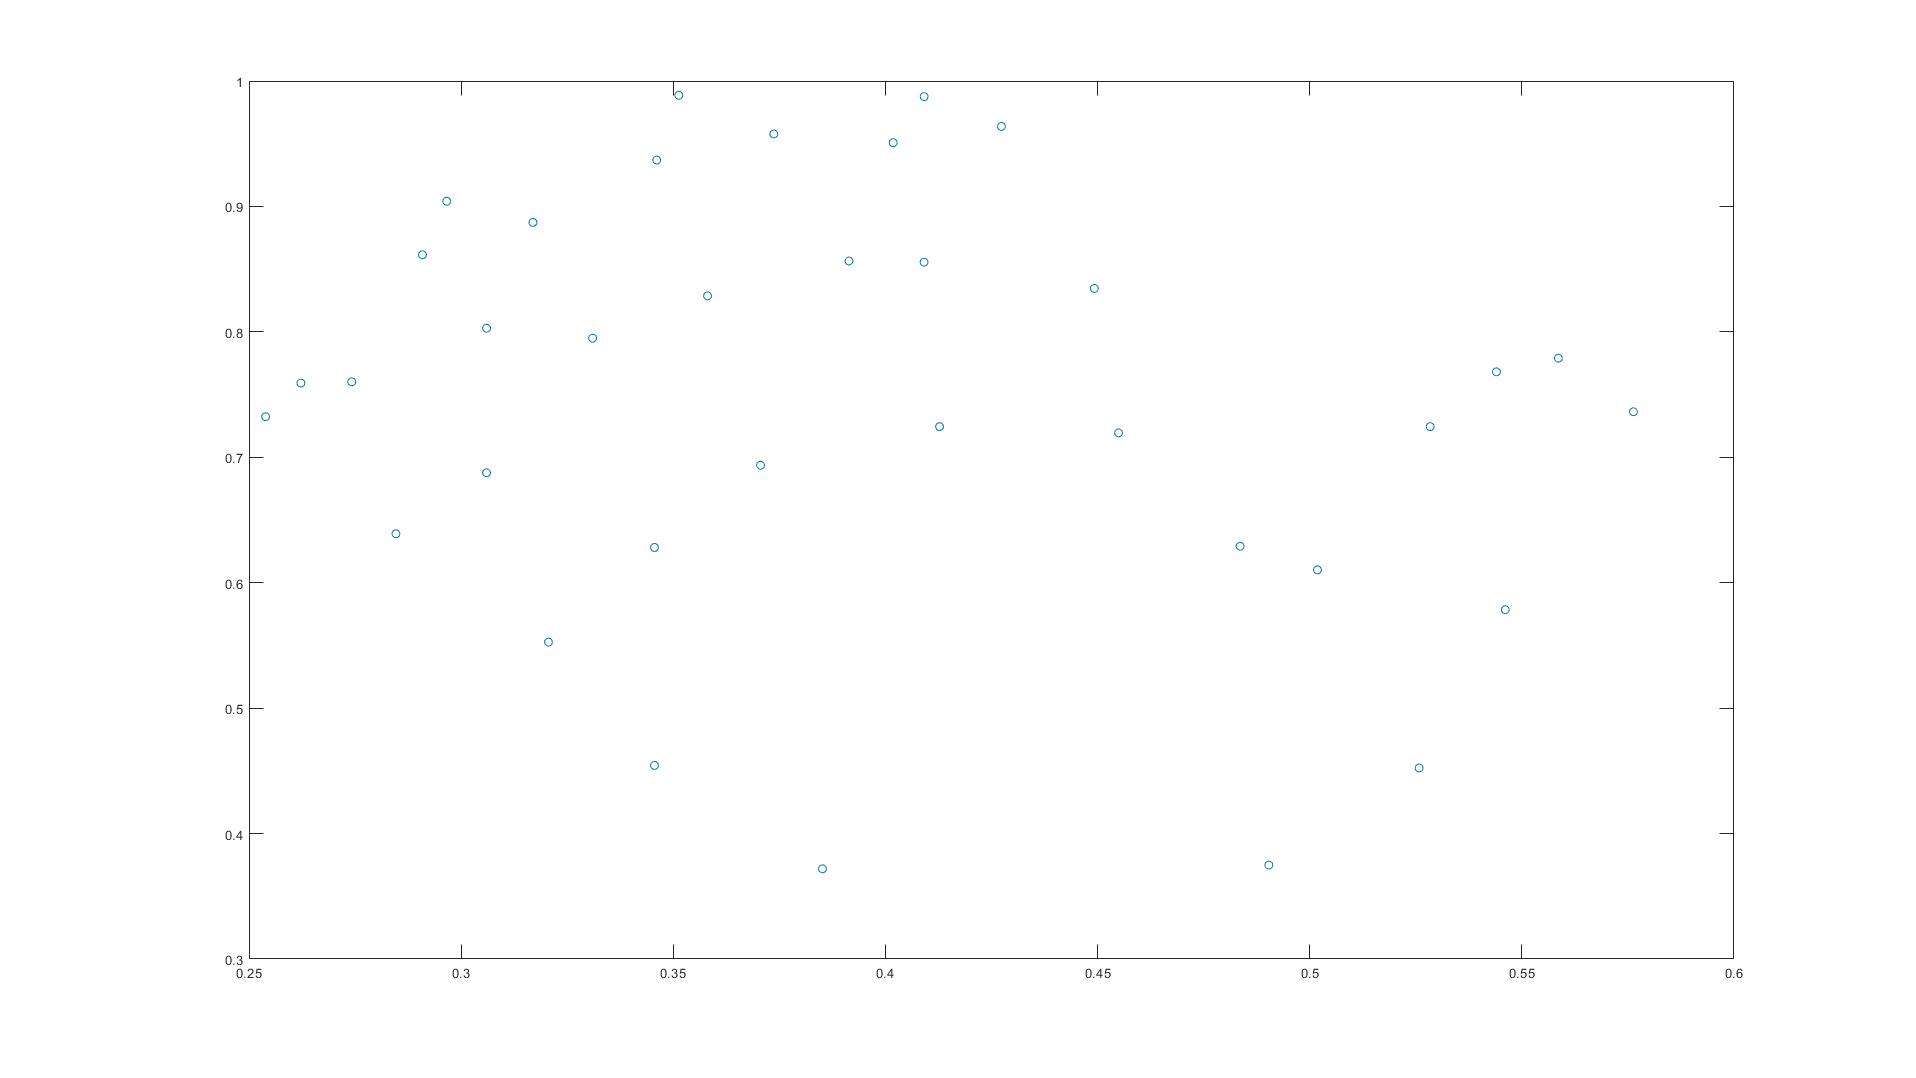

plot(x,y,'o',p.*cos(t),p.*sin(t),'-',...
s.*cos(t),s.*sin(t),'-')

**Exercici 1.2**

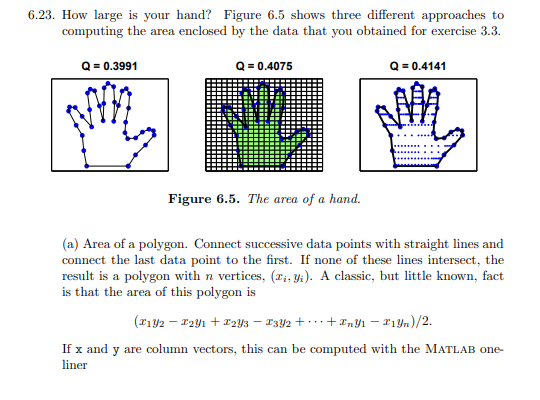

area = (x'*y([2:n 1]) - x([2:n 1])'*y)/2

area =        -0.0961948651108893


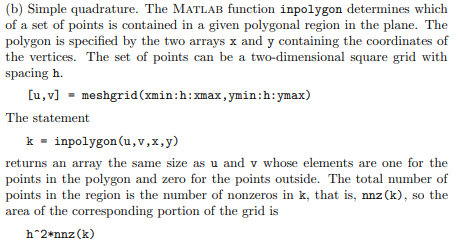

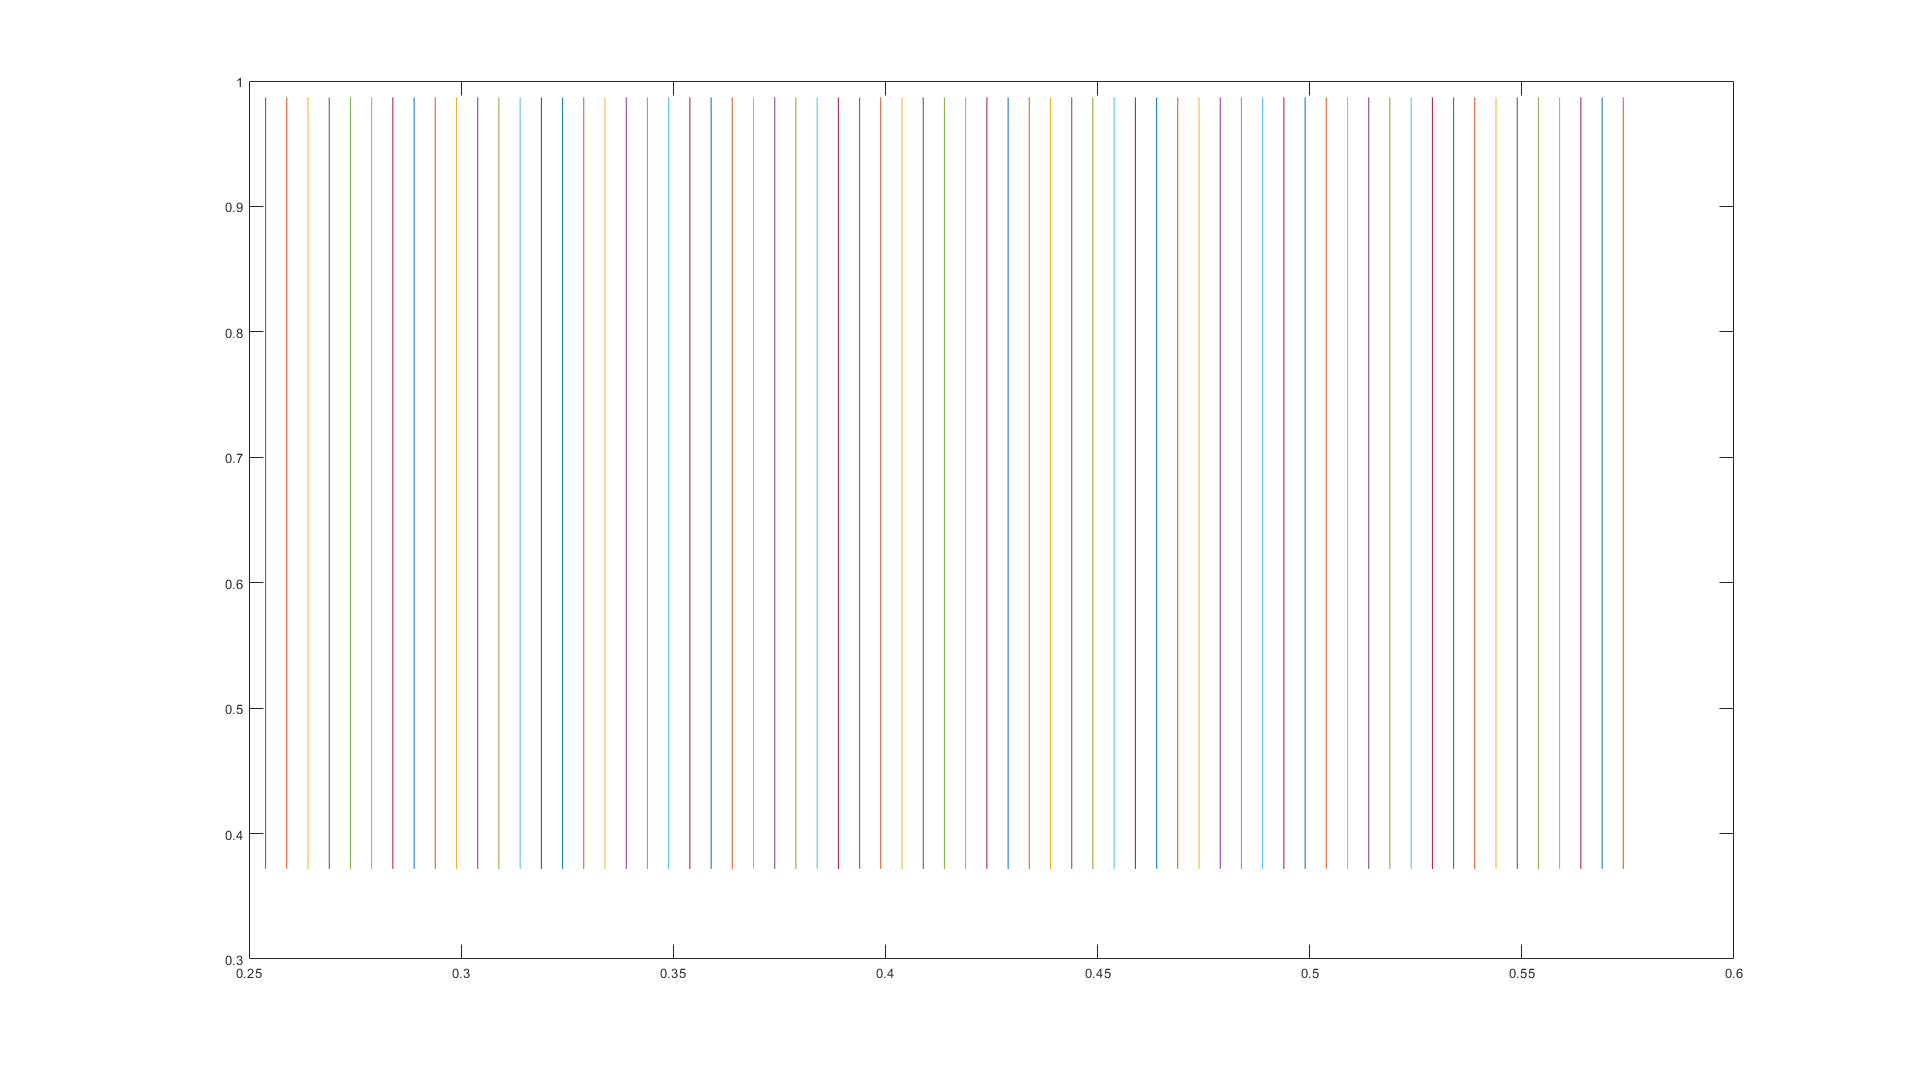

h = 0.005;
xmin = min(x);
xmax = max(x);
ymin = min(y);
ymax = max(y);
[u, v] = meshgrid(xmin:h:xmax,ymin:h:ymax);
k = inpolygon(u,v,x,y);
plot(u,v);

nnz(k);
radi = (h^2)*nnz(k)

radi =                    0.09615


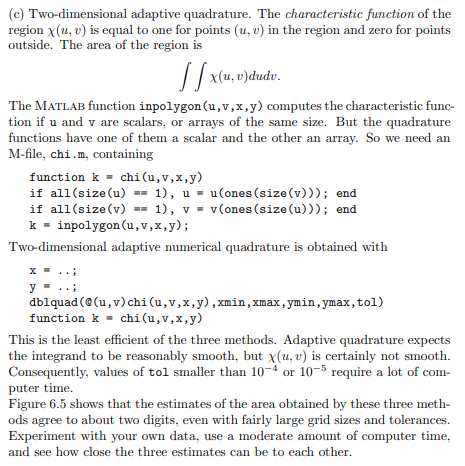

tol = 10^(-4);
radi = dblquad(@(u,v)chi(u,v,x,y),xmin,xmax,ymin,ymax,tol)

radi =         0.0971777410991221


# Exercici 2

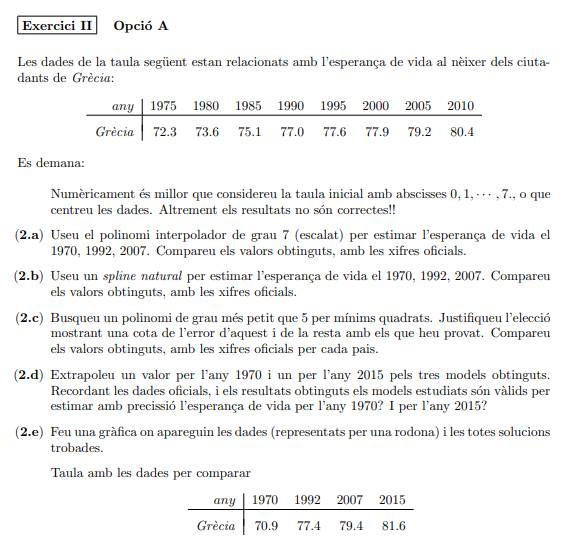

**2.a**

clear
x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];

# Polinomi interpolador grau 7

grau = 7;
[p, ~, mu] = polyfit(x,y,grau);
aproximado = polyval(p,anys,[], mu);
error = error_absoluto(valor_exacto,aproximado);
t = array2table(p, 'RowNames', {'coeficient polinomi'})

t = 1×8 table
                                  p1                   p2                  p3                   p4                  p5                  p6                   p7                 p8       
                           _________________    ________________    _________________    ________________    ________________    _________________    ________________    _______________

    coeficient polinomi    0.703353483285026    -1.0950000000001    -2.78935644459486    3.84687500000029    3.50060151313737    -3.82986979166686    1.32862720284717    77.452978515625


t1 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2010'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

t1 = 3×4 table
                       1970                 1992                  2007                2010       
                 ________________    ___________________    ________________    _________________

    valor                    70.9                   77.4                49.4                 81.6
    aproximat    50.7999999999965           77.392127232    79.8143557120001     81.7000000000011
    desviat      20.1000000000035    0.00787276799995595    30.4143557120001    0.100000000001074


**2.b**

# Spline

x = (x-1975)/(35/7);
anys2 = (anys-1975)/(35/7);
aproximado = interp1(x,y,anys2,'spline');
error = error_absoluto(valor_exacto,aproximado);
t2 = array2table([valor_exacto;aproximado; error], 'VariableNames', {'1970' ,'1992' ,'2007' ,'2010'}, 'RowNames', {'valor', 'aproximat' 'desviat'})

t2 = 3×4 table
                       1970                 1992                2007                2010      
                 _________________    _________________    _______________    ________________

    valor                     70.9                 77.4               49.4                81.6
    aproximat     70.3143540669856     77.3947827751196    79.787414354067    79.7961722488039
    desviat      0.585645933014376    0.005217224880397    30.387414354067    1.80382775119611


**2.c**

# Polinomio minimos cuadrados

n = 5;
error = zeros(n,length(anys2)+1);
RowNames = {};
for i = 1:n
    coeficientes = polinomio_interpolador_minimos_cuadrados(x, y, i);
    aproximado = polyval(coeficientes,anys2);
    RowNames{i} = strcat('grau ', int2str(i));
    e = error_absoluto(valor_exacto, aproximado);
    error(i,:) = [e, sum(e,2)];
end
t3 = array2table(error,'VariableNames', {'1970' ,'1992' ,'2007' ,'2010', 'Desviacio'}, 'RowNames',RowNames)

t3 = 5×5 table
                   1970                 1992                 2007                 2010              Desviacio    
             _________________    _________________    ________________    __________________    ________________

    grau1    0.717857142857156    0.874047619047616     30.472380952381    0.0571428571428498    32.1214285714286
    grau2    0.201785714285364    0.552785714285818    30.2786428571429     0.862499999999713    31.8957142857138
    grau3      1.1142857142829    0.535752380952502     30.233736796537    0.0499999999976239      31.93377489177
    grau4     1.28035714287641    0.275640952379177    29.9764118614701       2.4446428571583     33.977052813884
    grau5     4.32499999959218    0.252492923

**2.d**

**2.e**

# Dades

x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
scatter(x,y, 'DisplayName','Dades 1');
anys = [1970 1992 2007 2015];
valor_exacto = [70.9 77.4 49.4 81.6];
hold on;
scatter(anys, valor_exacto, 'DisplayName','Dades 2');

# Polinomi interpolador grau 7(PLOT)

grau = 7;
[coeficientes, ~, mu] = polyfit(x,y,grau);
xplot = 1970:2015;
yplot = polyval(coeficientes,xplot,[], mu);
hold on;
plot(xplot,yplot, 'DisplayName','polinomi grau 7');

# Spline(PLOT)

x = (x-1975)/(35/7);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = interp1(x,y,xplot_centrado,'spline');
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','spline');

# Polinomio minimos cuadrados(Plot)

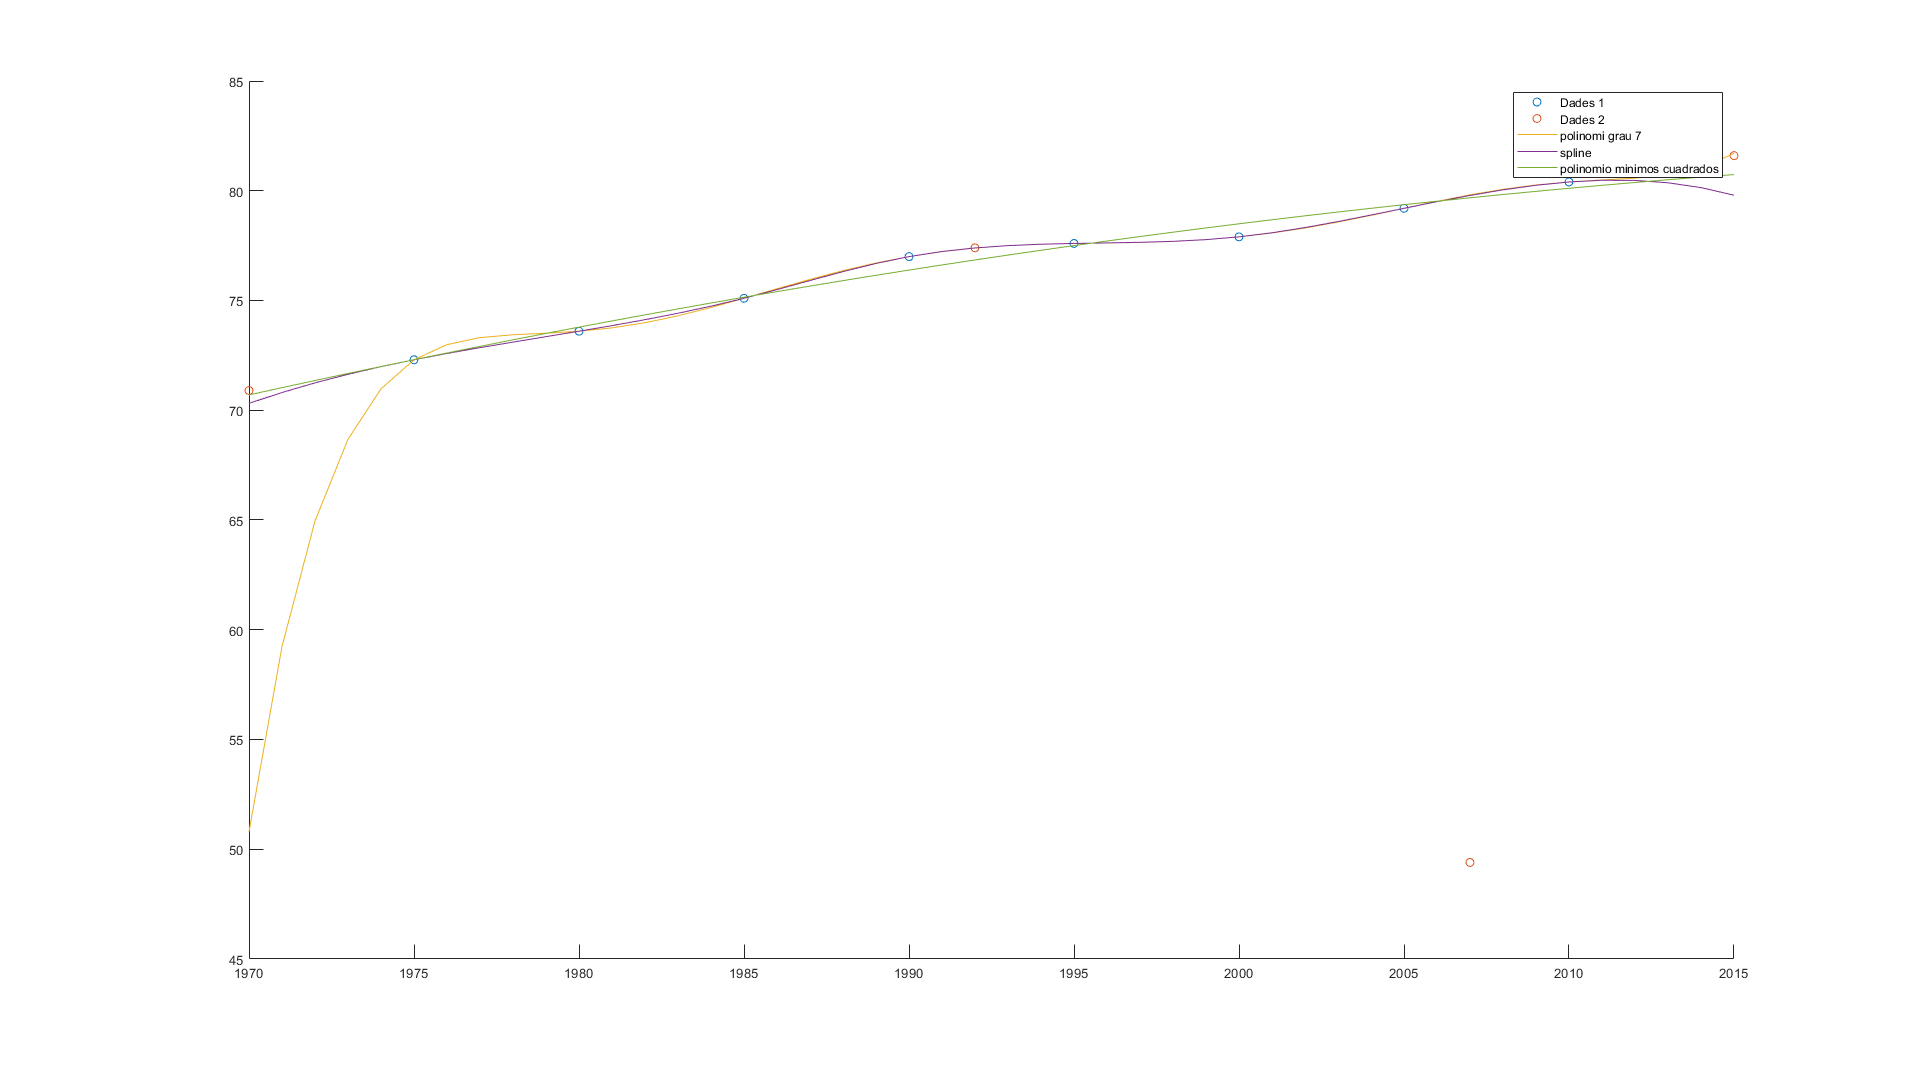

grado = 2;
[coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado);
xplot_centrado = ((1970:2015)-1975)/(35/7);
yplot = polyval(coeficientes,xplot_centrado);
xplot = 1970:2015;
hold on;
plot(xplot,yplot, 'DisplayName','polinomio minimos cuadrados');
legend

# Exercici 3

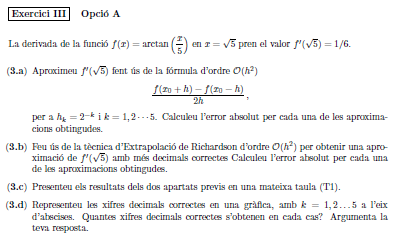

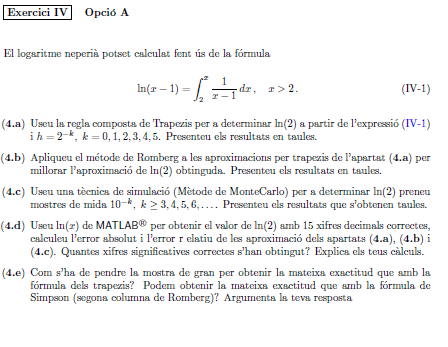

function [coeficientes] = polinomio_interpolador_minimos_cuadrados(x, y, grado)
    A = ones(length(x),grado+1);
    i = grado;
    while(i  > 0)
        A(:,((grado+1)-i)) = (x').^i;
        i = i-1;
    end
    b = y';
    coeficientes  = minimos_cuadrados(A,b)';
end
function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;

end

function [error_absoluto] = error_absoluto(valor_exacto, valor_aproximado)
    error_absoluto = abs(valor_exacto-valor_aproximado);
end